### Setup

clear variables 
% Sound driver parameters
Buffersize = 1024;
RecorderChannelMapping = [1 2 3 4 5 6];

% Struct for often used constants
Constants = struct( ...
    'Samplerate', 48000, ...
    'AmountOfMicrophones', length(RecorderChannelMapping), ...
    'UCARadius', 0.40 / 2, ...
    'SpeedOfSound', 343, ...
    'SoundOutputOffset', 0.116 / 2, ... % From Genelec 8010A datasheet (half depth)
    'AlphaOffset', 30, ... % Offset betweeen x-axis and mic 1 in degrees
    'AmountOfTaus', 301, ...
    'AmountOfPhis', 360, ...
    'AmountOfOmegas', 401 ...
    );


% Distance parameters
OffsetMin = (2518 - 0.15 / Constants.SpeedOfSound * Constants.Samplerate) / Constants.Samplerate * Constants.SpeedOfSound;
OffsetMax = (2534 - 0.25 / Constants.SpeedOfSound * Constants.Samplerate) / Constants.Samplerate * Constants.SpeedOfSound;
MinDistance = 0.5;
MaxDistance = 2;

% Execution paths
LiveRecording =false;
Synthesized = true;

Debugging = false;
Continuously = false;

### Loading sound

% Define the sound we want to play
if Synthesized
    load("synthesized_signals.mat")
    ProbeSound = signals.clean;
    Constants.SignalLength = length(ProbeSound);
    Constants.AmountOfMicrophones = 3;
    Constants.AlphaOffset = 60;
    Constants.Samplerate = 24000;
else
    t = 0:1/Constants.Samplerate:0.5;
    ProbeSound = transpose(chirp(t, 50, t(end), 1000, "linear"));
    Constants.SignalLength = length(ProbeSound);

    % Since the sound we wish to play is larger than than buffersize. We need to
    % partition the sound that is going to be played, such that it fits with the
    % buffersize. We choose to pad the sound with silence, such that it fits
    ElementsToAdd = (Buffersize - mod(length(ProbeSound), Buffersize));
    ProbeSound = padarray(ProbeSound, ElementsToAdd, 'post');
    
    % Adding silent frames to the end of the probe sound and scaling it
    SilentFramesToAdd = 24;
    Amplitude = 1.22;
    ProbeSound = padarray(ProbeSound, Buffersize*SilentFramesToAdd, 'post');
    ProbeSound = ProbeSound * Amplitude;
    
    % Reshape the sounds to fit with the buffersize
    SoundPartitions = reshape(ProbeSound, Buffersize, []);
end

### Precalculations

PreCalcStart = tic;
% Calculate angular position of microphones
Constants.Betas = UCAangles(Constants.AmountOfMicrophones, Constants.AlphaOffset);

% Define linspaces for Phis, Taus, Omegas
Phis = linspace(0, deg2rad(359), Constants.AmountOfPhis); % In rad
Taus = linspace(MinDistance, MaxDistance, Constants.AmountOfTaus) * 2 / Constants.SpeedOfSound * Constants.Samplerate; % In samples
Omegas = linspace(100, 12000, Constants.AmountOfOmegas); % In Hz
OmegasAngular = Omegas * 2 * pi %/ Constants.Samplerate; % In rad/sample

OmegasAngular = 	1.0e+04 *

    0.0100    0.0130    0.0159    0.0189    0.0219    0.0249    0.0278    0.0308    0.0338    0.0368    0.0398    0.0427    0.0457    0.0487    0.0517    0.0546    0.0576    0.0606    0.0635    0.0665    0.0695    0.0725    0.0755    0.0784    0.0814    0.0844    0.0873    0.0903    0.0933    0.0963    0.0993    0.1022    0.1052    0.1082    0.1111    0.1141    0.1171    0.1201    0.1231    0.1260    0.1290    0.1320    0.1349    0.1379    0.1409    0.1439    0.1469    0.1498    0.1528    0.1558


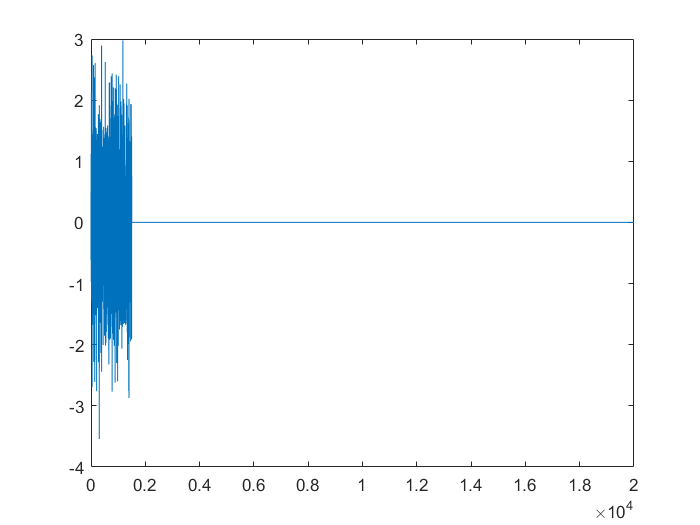


figure
plot(ProbeSound)

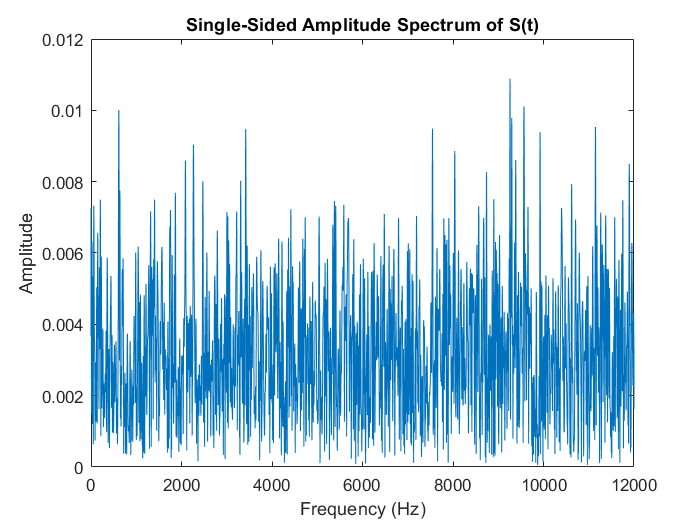


% Find the one sided FFT of the received sound
ProbeFFT = OneSidedFFT(ProbeSound, ...
    "Plot", true, "Samplerate", Constants.Samplerate);

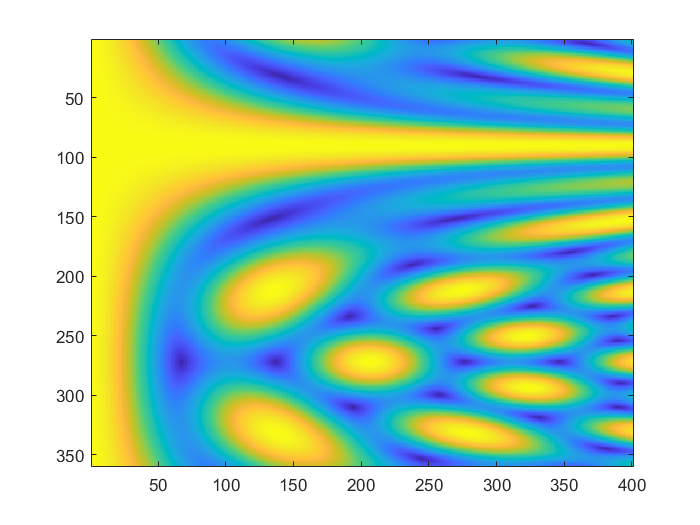

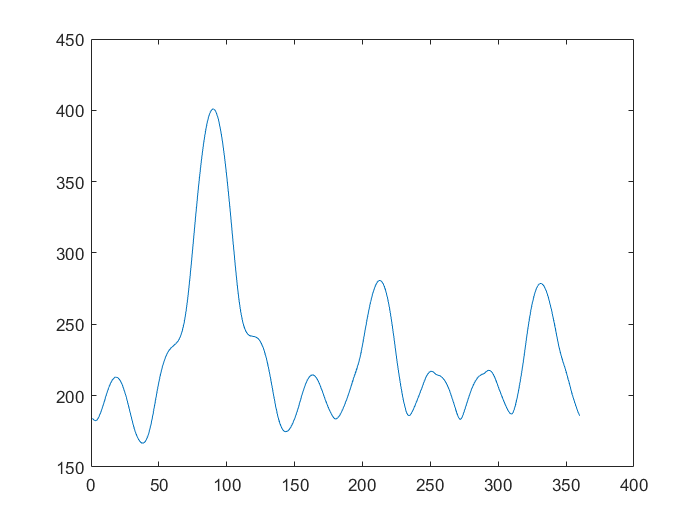


% Define linspaces for indexing Omegas
OmegasBinIndices = linspace(0, Constants.AmountOfOmegas-1, Constants.AmountOfOmegas);
OmegasFFTIndices = round(Omegas * Constants.SignalLength / Constants.Samplerate, 0);

% Find the beamformer weights
wDS = BeamformerDS(Phis, OmegasAngular, Constants); % <-- Her burde vi nok bare udregne alle steering vectors, således vi bare kan bruge dem senere til udregningen af Yk og vores beamformer

wDSHermitian = pagectranspose(wDS); % Hermitian transpose of wDS

% Calculate Zbar
Zbar = CalculateZbar(ProbeFFT(OmegasFFTIndices), Phis, Taus, OmegasBinIndices, Constants);

toc(PreCalcStart)

Elapsed time is 7.022830 seconds.


%clear OmegasBinIndices ProbeFFT 

### Sound driver

if LiveRecording
    SoundDriver = audioPlayerRecorder( ...
        "SampleRate", Constants.Samplerate, ...
        "Device", "ZOOM Audio IF with Rec ASIO", ... % You must choose your own device
        'SupportVariableSize', true, ...
        "BufferSize", Buffersize, ...
        "RecorderChannelMapping", RecorderChannelMapping, ...
        "BitDepth", '32-bit float' ...  
        );
    
    if Debugging
        InputScope = timescope( ...
            'Name', 'Input', ...
            'SampleRate', Constants.Samplerate, ...
            'BufferLength', Buffersize, ...
            'AxesScaling', "auto", ...
            'TimeSpanSource', "property", ... 
            'TimeSpan', 5 ...
            );
        
        OutputScope = timescope( ...
            'Name', 'Output', ...
            'SampleRate', Constants.Samplerate, ...
            'BufferLength', Buffersize, ...
            'AxesScaling', "auto", ...
            'TimeSpanSource', "property", ... 
            'TimeSpan', 5 ...
            );
        
        InputScope.show;
        OutputScope.show;
    end
end

### Echolocation

while true
    EchoStart = tic;
    if Synthesized
        ReceivedSound = signals.reflec;
    elseif LiveRecording
        % Play the sound and store the recorded data into ReceivedSound
        ReceivedSound = PlayAndRecordSound(SoundDriver, SoundPartitions, Constants.AmountOfMicrophones);
        %ReceivedSound = RemoveDelay(ReceivedSound, Constants);
    else
        ReceivedSound = struct2array(load('Recordings\1.2Meter30Degree.mat'));
    end
    
    % Find the one sided FFT of the received sound
    ReceivedFFT = transpose(OneSidedFFT(ReceivedSound));
    
    for i = 1: Constants.AmountOfMicrophones
        figure
        plot(ReceivedSound(:, i))
        title("Mic" + i + ": Time domain")
        figure
        plot(ReceivedFFT(i, :))
        title("Mic" + i + ": Frequency domain, All frequencies")
        figure
        plot(ReceivedFFT(i, OmegasFFTIndices))
        title("Mic" + i + ": Frequency domain, Specified frequencies")
    end
    
    Ybar = CalculateYbar(ReceivedFFT, OmegasFFTIndices, wDSHermitian, Constants, ...
       "Plot", true);
    
    CostMatrix = CostFunction(Ybar, Zbar, Constants, ...
        "Plot", true);
    
    [Angle, Distance] = Estimator(Phis, Taus, CostMatrix, Constants)
    

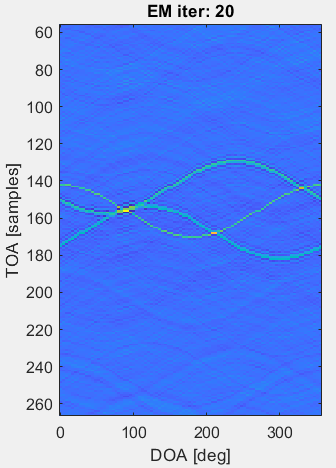 Distance: 1.11, DOA: 90

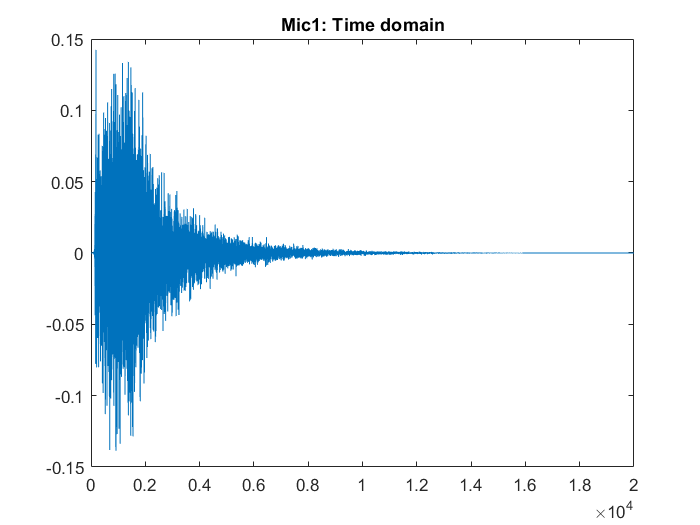

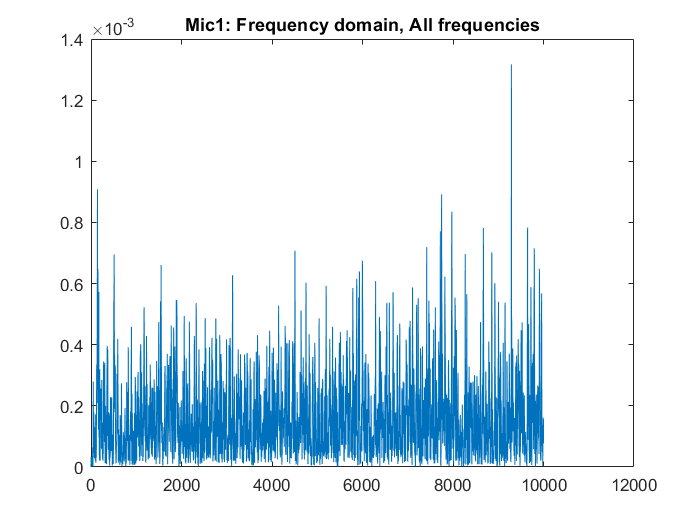

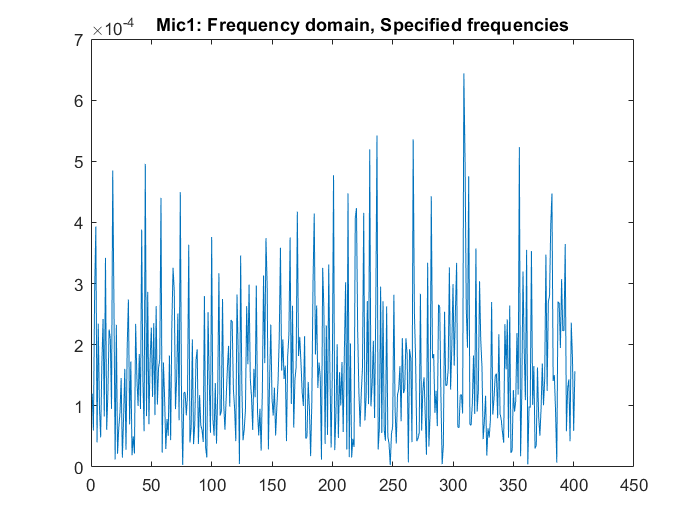

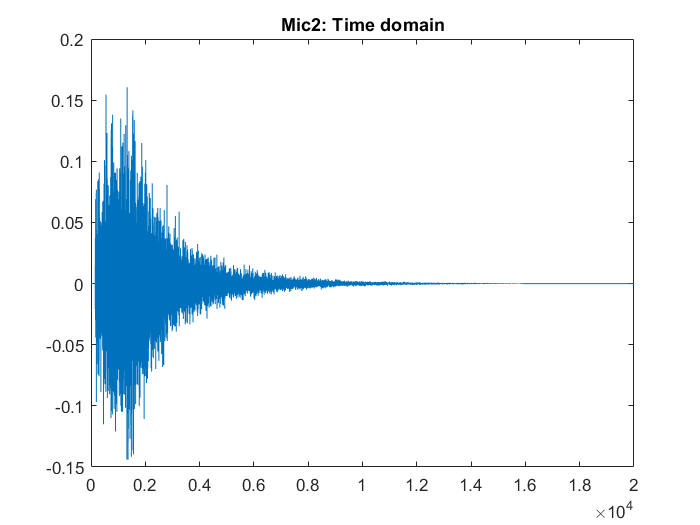

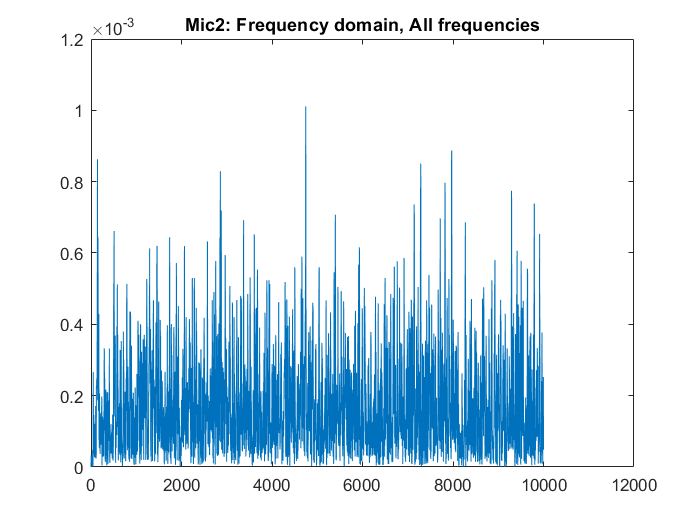

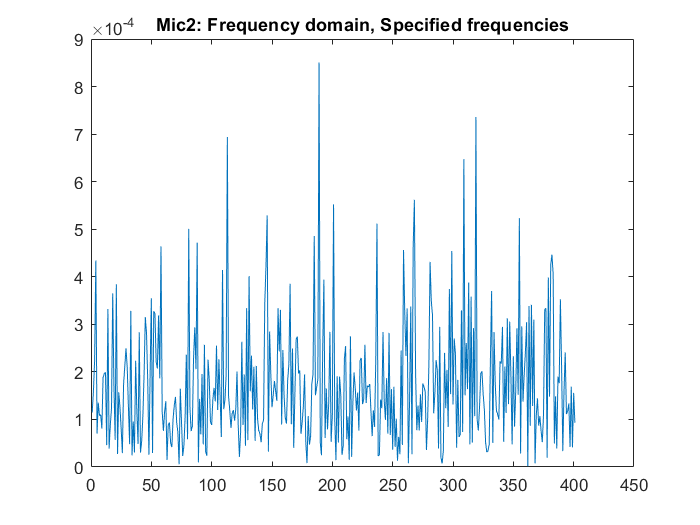

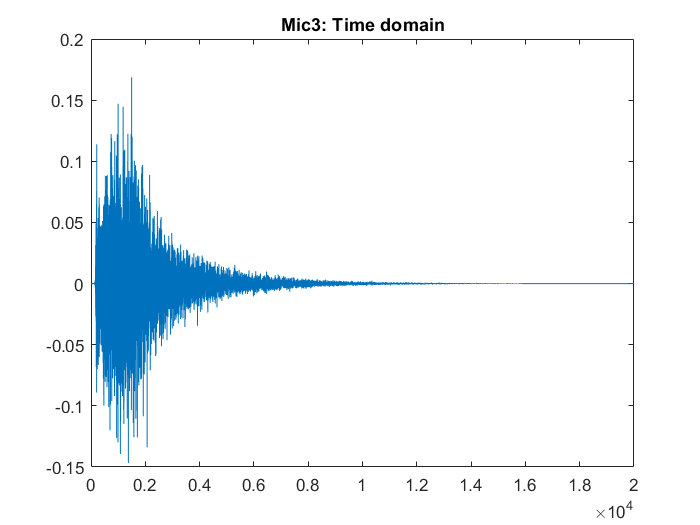

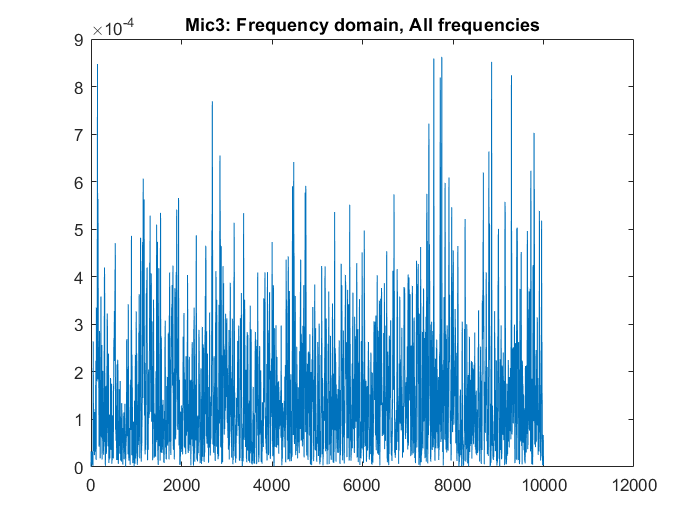

Angle = 0

Distance = 1.4850

Elapsed time is 2.283653 seconds.


    
    toc(EchoStart)
    
    if ~Continuously 
        break;
    end
end

SaveSound = ReceivedSound;